x=[1.01, 2.2, 2.9, 4.03, 5.32 ,6.22, 8.56, 9.09]

x =     1.0100    2.2000    2.9000    4.0300    5.3200    6.2200    8.5600    9.0900


y=[18.5, 76.2, 150.5, 365, 780, 1265, 3250, 7099]

y =    1.0e+03 *

    0.0185    0.0762    0.1505    0.3650    0.7800    1.2650    3.2500    7.0990


xt=transpose(x)

xt =     1.0100
    2.2000
    2.9000
    4.0300
    5.3200
    6.2200
    8.5600
    9.0900


van=[]


van =

     []



parfor i=1:length(xt)
    a=xt(i)
    van=[van;[a^3 a^2 a 1]]
end
coeff=(transpose(van)*van)\transpose(van)*transpose(y)

coeff =    1.0e+03 *

    0.0366
   -0.3981
    1.4075
   -1.2423


points=[]


points =

     []



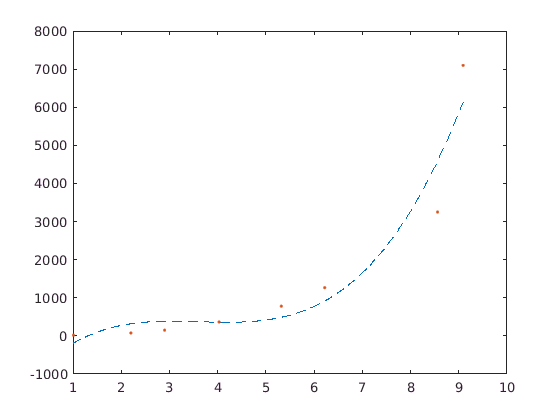

for i=1:.01:max(x)
    points=[points coeff_point(i,coeff)];
end
plot(1:.01:max(x),points,'--');hold on;scatter(x,y,'.');hold off;

function y = coeff_point(x,coeff)
    y=coeff(1)*x^3+coeff(2)*x^2+coeff(3)*x+coeff(4);
end